% 根据病人的年龄和身高预测血压最高值
% 采用kNN解决回归问题
% 具体使用fitcknn和predict函数

% 导入医院数据集
load hospital;
X = [hospital.Age hospital.Weight];
Y= hospital.BloodPressure(:,1);

% 5个病人的自变量数据，没有高血压的真值
X_new = [20 162; 30 169; 40 168; 50 170; 60 171];   % 5个新病人


% 采用fitcknn和predict 进行预测
Mdl = fitcknn(X,Y,'NumNeighbors',2);
Y_pre = predict(Mdl,X)

Y_pre =    124
   109
   113
   117
   122
   121
   123
   115
   115
   118



% 对5个病人进行预测
Y_pre_new = predict(Mdl,X_new)

Y_pre_new =    127
   120
   128
   125
   125


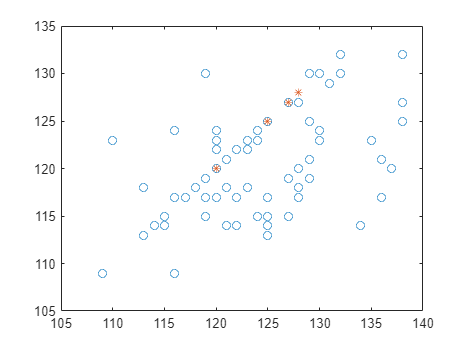



% 比较结果
figure;
plot(Y,Y_pre,'o');hold on;
plot(Y_pre_new,Y_pre_new,'*');